
dataFolderTrain = "G:\Signature_Set3\BHSig260";
imdsTrain = imageDatastore(dataFolderTrain, ...
    'IncludeSubfolders',true, ...
    'LabelSource','none');

files = imdsTrain.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),'_');
imdsTrain.Labels = categorical(labels);
imgSize = size(readimage(imdsTrain,1));
idxs = randperm(numel(imdsTrain.Files),8);

for i = 1:numel(idxs)
    subplot(4,2,i)
    imshow(readimage(imdsTrain,idxs(i)))
    title(imdsTrain.Labels(idxs(i)), "Interpreter","none");
end
batchSize = 10;
    classes = unique(imdsTrain.Labels);
    classesChoice = randperm(numel(classes),2);
[pairImage1,pairImage2,pairLabel] = getSiameseBatch(imdsTrain,batchSize);
size(pairImage1)

ans =    224   224     1    10


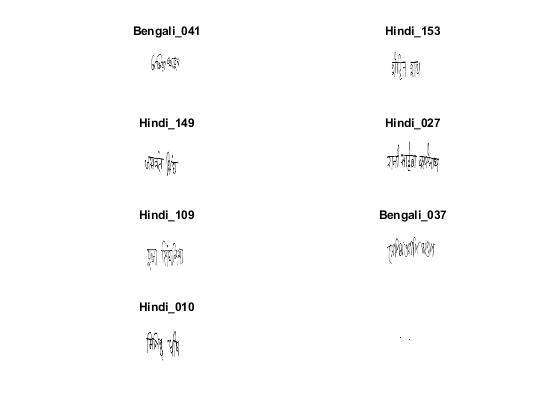

imshow(pairImage1(:,:,:,1))

numel(imdsTrain)

ans = 1

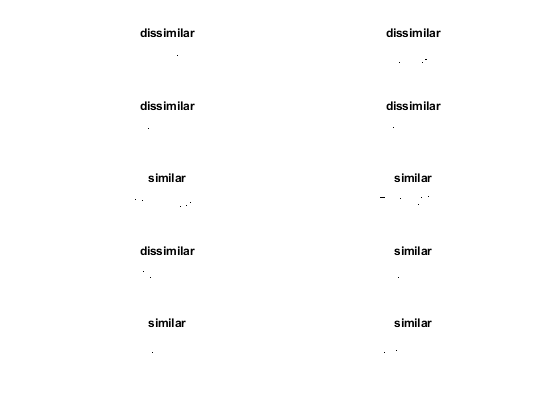

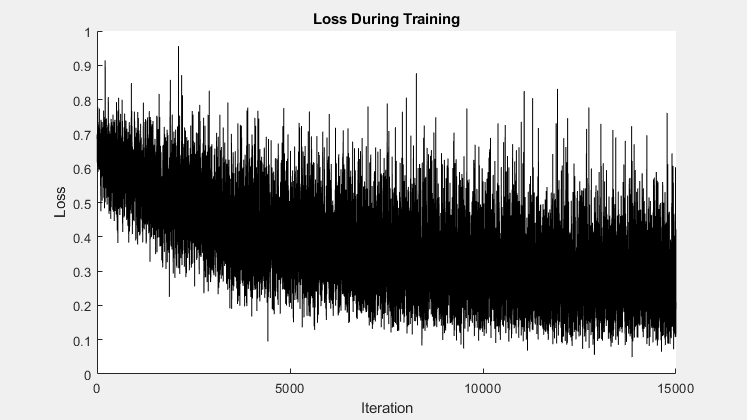

for i = 1:batchSize    
    if pairLabel(i) == 1
        s = "similar";
    else
        s = "dissimilar";
    end
    subplot(5,2,i)   
    imshow([pairImage1(:,:,:,i) pairImage2(:,:,:,i)]);
    title(s)
end
initialSection = [
    imageInputLayer([224 224 1],"Name","input1",'Normalization','none')
    convolution2dLayer(7,64,"Stride",2,"Padding",3,"BiasLearnRateFactor",0,"Name","conv1")
    batchNormalizationLayer("Name","bn_conv1")
    reluLayer("Name","conv1_relu")
    maxPooling2dLayer(3,"Stride",2,"Padding",[0 1 0 1],"Name","pool1")];
lgraph = layerGraph(initialSection);
middleLayer = [
addAndConnectResNetSection(lgraph, ...
    lgraph.Layers(end).Name, ...    % Layer to connect to
    "res2", ...                     % Name of ResNet section
    64, ...                         % Number of filters in the first 1-by-1 convolutions
    64, ...                         % Number of filters in the 3-by-3 convolutions
    256, ...                        % Number of filters in the last 1-by-1 convolutions
    1, ...                          % Stride of the first convolution of the section
    {'a','b','c'});                 % Names of the residual units


addAndConnectResNetSection(lgraph, ...
    lgraph.Layers(end).Name, ...
    "res3", ...
    128, ...
    128, ...
    512, ...
    2, ...
    {'a','b1','b2','b3'});

addAndConnectResNetSection(lgraph, ...
    lgraph.Layers(end).Name, ...
    "res4", ...
    256, ...
    256, ...
    1024, ...
    2, ...
    {'a','b1','b2','b3','b4','b5','b6','b7','b8','b9','b10','b11','b12',...
    'b13','b14','b15','b16','b17','b18','b19','b20','b21','b22'});

addAndConnectResNetSection(lgraph, ...
    lgraph.Layers(end).Name, ...
    "res5", ...
    512, ...
    512, ...
    2048, ...
    2, ...
    {'a','b','c'})];

finalSection = [
    averagePooling2dLayer(7,"Stride",7,"Name","pool5")
    fullyConnectedLayer(4096,"Name","fc1")];

lastLayerName = lgraph.Layers(end).Name;
lgraph = addLayers(lgraph,finalSection);
lgraph = connectLayers(lgraph,lastLayerName,"pool5");

dlnet = dlnetwork(lgraph);

fcWeights = dlarray(0.01*randn(1,4096));
fcBias = dlarray(0.01*randn(1,1));

fcParams = struct(...
    "FcWeights",fcWeights,...
    "FcBias",fcBias);

numIterations = 15000;
miniBatchSize = 18;

learningRate = 6e-5;
trailingAvgSubnet = [];
trailingAvgSqSubnet = [];
trailingAvgParams = [];
trailingAvgSqParams = [];
gradDecay = 0.9;
gradDecaySq = 0.99;

executionEnvironment = "auto";
plots = "training-progress";

plotRatio = 16/9;

if plots == "training-progress"
    trainingPlot = figure;
    trainingPlot.Position(3) = plotRatio*trainingPlot.Position(4);
    trainingPlot.Visible = 'on';
    
    trainingPlotAxes = gca;
    
    lineLossTrain = animatedline(trainingPlotAxes);
    xlabel(trainingPlotAxes,"Iteration")
    ylabel(trainingPlotAxes,"Loss")
    title(trainingPlotAxes,"Loss During Training")
end

%Loop over mini-batches.
for iteration = 1:numIterations
    
  %  Extract mini-batch of image pairs and pair labels
    [X1,X2,pairLabels] = getSiameseBatch(imdsTrain,miniBatchSize);
    
   % Convert mini-batch of data to dlarray. Specify the dimension labels
   % 'SSCB' (spatial, spatial, channel, batch) for image data
    dlX1 = dlarray(single(X1),'SSCB');
    dlX2 = dlarray(single(X2),'SSCB');
    %If training on a GPU, then convert data to gpuArray.
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        dlX1 = gpuArray(dlX1);
        dlX2 = gpuArray(dlX2);
    end  
    
    %Evaluate the model gradients and the generator state using
    %dlfeval and the modelGradients function listed at the end of the
    %example.
    [gradientsSubnet, gradientsParams,loss] = dlfeval(@modelGradients,dlnet,fcParams,dlX1,dlX2,pairLabels);
    lossValue = double(gather(extractdata(loss)));
    
    %Update the Siamese subnetwork parameters.
    [dlnet,trailingAvgSubnet,trailingAvgSqSubnet] = ...
        adamupdate(dlnet,gradientsSubnet, ...
        trailingAvgSubnet,trailingAvgSqSubnet,iteration,learningRate,gradDecay,gradDecaySq);
    
    %Update the fullyconnect parameters.
    [fcParams,trailingAvgParams,trailingAvgSqParams] = ...
        adamupdate(fcParams,gradientsParams, ...
        trailingAvgParams,trailingAvgSqParams,iteration,learningRate,gradDecay,gradDecaySq);
      
 %   Update the training loss progress plot.
    if plots == "training-progress"
        addpoints(lineLossTrain,iteration,lossValue);
    end
    drawnow;
end 


dataFolderTest = "G:\Signature_Set3\BHSig260";
imdsTest = imageDatastore(dataFolderTest, ...
    'IncludeSubfolders',true, ...
    'LabelSource','none');    

files = imdsTest.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),'_');
imdsTest.Labels = categorical(labels);

numClasses = numel(unique(imdsTest.Labels))

numClasses = 260


accuracy = zeros(1,5);
accuracyBatchSize = 150;

for i = 1:5
    
    % Extract mini-batch of image pairs and pair labels
    [XAcc1,XAcc2,pairLabelsAcc] = getSiameseBatch(imdsTest,accuracyBatchSize);
    
    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % 'SSCB' (spatial, spatial, channel, batch) for image data.
    dlXAcc1 = dlarray(single(XAcc1),'SSCB');
    dlXAcc2 = dlarray(single(XAcc2),'SSCB');
    
    % If using a GPU, then convert data to gpuArray.
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
       dlXAcc1 = gpuArray(dlXAcc1);
       dlXAcc2 = gpuArray(dlXAcc2);
    end    
    
    % Evaluate predictions using trained network
    dlY = predictSiamese(dlnet,fcParams,dlXAcc1,dlXAcc2);
   
    % Convert predictions to binary 0 or 1
    Y = gather(extractdata(dlY));
    Y = round(Y);
    
    % Compute average accuracy for the minibatch
    accuracy(i) = sum(Y == pairLabelsAcc)/accuracyBatchSize;
end

% Compute accuracy over all minibatches
averageAccuracy = mean(accuracy)*100

averageAccuracy = 72.4000

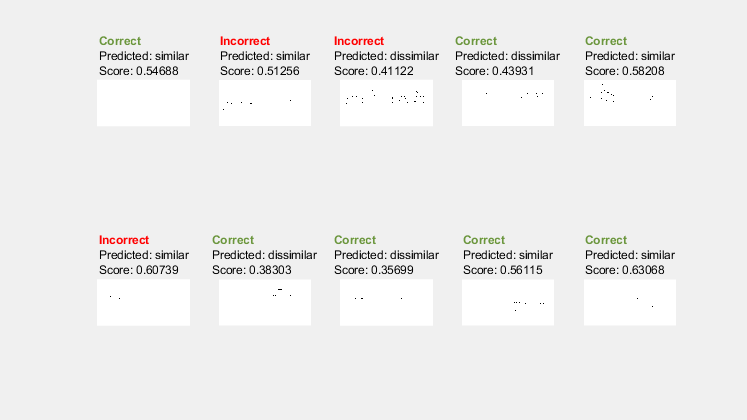


testBatchSize = 10;

[XTest1,XTest2,pairLabelsTest] = getSiameseBatch(imdsTest,testBatchSize);
    
% Convert test batch of data to dlarray. Specify the dimension labels
% 'SSCB' (spatial, spatial, channel, batch) for image data and 'CB' 
% (channel, batch) for labels
dlXTest1 = dlarray(single(XTest1),'SSCB');
dlXTest2 = dlarray(single(XTest2),'SSCB');

% If using a GPU, then convert data to gpuArray
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
   dlXTest1 = gpuArray(dlXTest1);
   dlXTest2 = gpuArray(dlXTest2);
end

% Calculate the predicted probability
dlYScore = predictSiamese(dlnet,fcParams,dlXTest1,dlXTest2);
YScore = gather(extractdata(dlYScore));

% Convert predictions to binary 0 or 1
YPred = round(YScore);    

% Extract data to plot
XTest1 = extractdata(dlXTest1);
XTest2 = extractdata(dlXTest2);

% Plot images with predicted label and predicted score
testingPlot = figure;
testingPlot.Position(3) = plotRatio*testingPlot.Position(4);
testingPlot.Visible = 'on';
    
for i = 1:numel(pairLabelsTest)
     
    if YPred(i) == 1
        predLabel = "similar";
    else
        predLabel = "dissimilar" ;
    end
    
    if pairLabelsTest(i) == YPred(i)
        testStr = "\bf\color{darkgreen}Correct\rm\newline";
        
    else
        testStr = "\bf\color{red}Incorrect\rm\newline";
    end
    
    subplot(2,5,i)        
    imshow([XTest1(:,:,:,i) XTest2(:,:,:,i)]);        
    
    title(testStr + "\color{black}Predicted: " + predLabel + "\newlineScore: " + YScore(i)); 
end